# AMPC vs. Reactive Controller (Jost Data)

This script compares the adaptive model preditctive controller to the reactive strategy used on patients in Jost et al. 2020. Since the Jost paper seems to dynamically change doses and dosing periods based on a given neutrophil measurement, the ampc method will use the same cycle lengths when determining doses of 6-MP.

TODO: Make another document for more details on procedure

clear all;
clc; 
close all; 

## Reading from DataSheet

Note: requires Data Sheet 1 and Data Sheet 2 from Jost to be in the same directory as this code. There may be a matlab warning when you read the files but it doesn't affect anything in the file data.

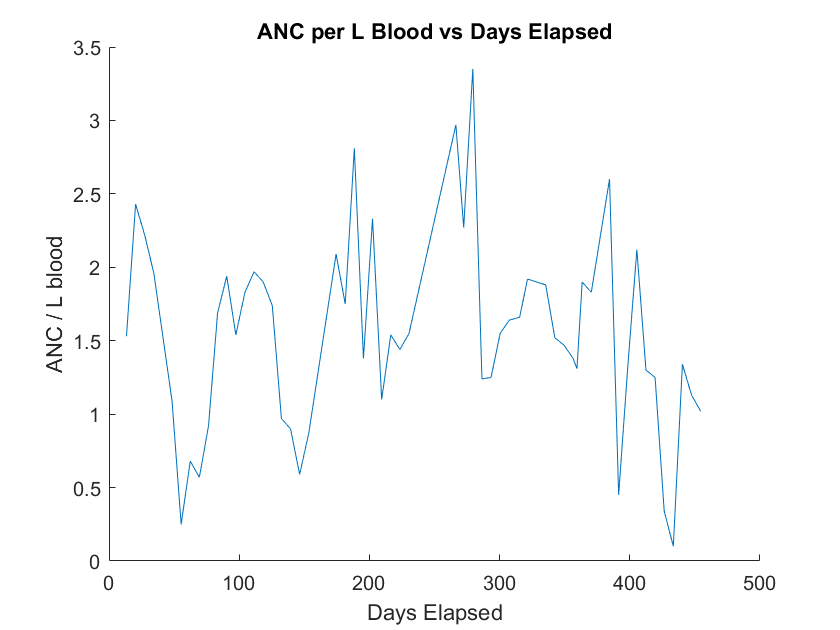

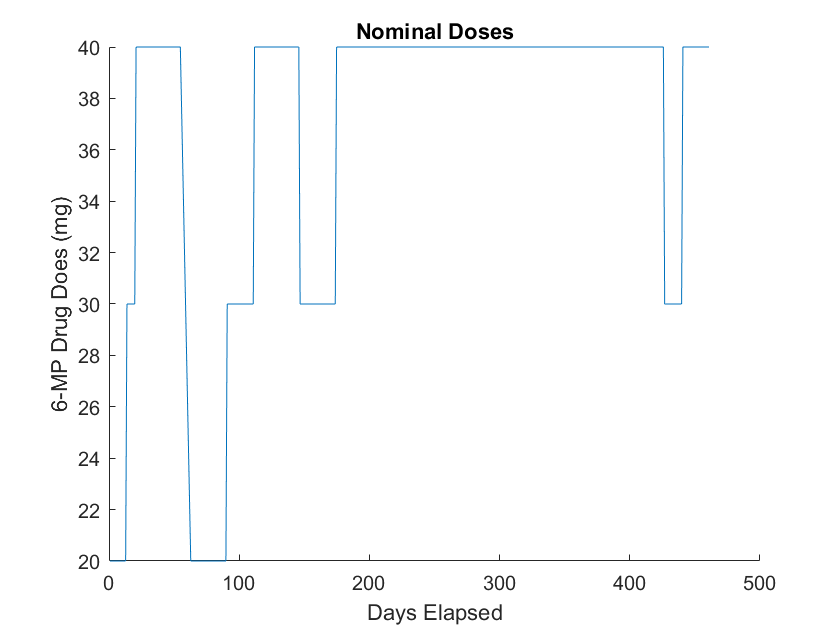

Start Time | End Time | Length


    0.7917   12.7920   13.0000
   13.7920   19.7920    7.0000
   20.7920   26.7920    7.0000
   27.7920   33.7920    7.0000
   34.7920   47.7920   14.0000
   48.7920   54.7920    7.0000
   62.7920   68.7920    7.0000
   69.7920   75.7920    7.0000
   76.7920   82.7920    7.0000
   83.7920   89.7920    7.0000
   90.7920   96.7920    7.0000
   97.7920  103.7900    7.0000
  104.7900  110.7900    7.0000
  111.7900  117.7900    7.0000
  118.7900  124.7900    7.0000
  125.7900  131.7900    7.0000
  132.7900  138.7900    7.0000
  139.7900  145.7900    7.0000
  146.7900  152.7900    7.0000
  153.7900  173.7900   21.0000
  174.7900  180.7900    7.0000
  181.7900  187.7900    7.0000
  188.7900  194.7900    7.0000
  195.7900  201.7900    7.0000
  202.7900  208.7900    7.0000
  209.7900  215.7900    7.0000
  216.7900  222.7900    7.0000
  223.7900  229.7900    7.0000
  230.7900  265.7900   36.0000
  266.7900  271.7900    6.0000
  272.7900  278.7900    7.0000
  279.7900  285.7900    7.0000
  286.79

Note that the length is +1 more than it seems because the dose carries onto the next day.


DataSheet1 = readmatrix("Data Sheet 1.csv");
DataSheet2 = readmatrix("Data Sheet 2.csv");

% Patients are numbered starting from 101 in the datasheet but for
% simplicity only put ids starting from 1 (e.g. 1 --> 101 in datasheet).
% If you enter -1, it uses population instead of patient parameters.
patientID = 4;

% population parameters (from Jost et al.)
population_params = [2.06; 0.146; 0.103; 0.866];
% change however you wish (see note above about theta 6 and 9)
population_params_guess = [2.15; 0.5; 0.25; 0.85]; %[0.75; 1.96; 1.35; 1.75]; %
population_bsa = 1.71; % Jost 2020 paper (Table 1, Body Surface Area range 0.47-1.98 m^2) - average population BSA

% get patient parameters
if patientID > 0
    p_actual = DataSheet1(patientID, 2:5)'; % turn into 4 by 1
    p_guess = population_params;
    
%     p_actual = [2.06; 0.146; 0.103; 0.866];
%     p_guess = [0.75; 1.96; 1.35; 1.75];
    
    patient_data    = [];
    patient_doses   = [];
    patient_evid    = [];
    patient_cycles  = [];
    simulation_time = [];
    cycle_start_time = 10000; % can be arbitrary because will be overwritten
    last_measurement = true;
    
    for k=1:length(DataSheet2)
        patient_id  = DataSheet2(k,1);
        time        = DataSheet2(k,2);
        measurement = DataSheet2(k,3);
        dose        = DataSheet2(k,5);
        evid        = DataSheet2(k,7);
        
        if patient_id - 100 == patientID
            bsa = DataSheet2(k,11);
            if measurement ~= 0
                patient_data = [patient_data; time measurement];
                if last_measurement == false
                    patient_cycles = [...
                        patient_cycles;...
                        cycle_start_time ...
                        prev_time ...
                        round(abs(prev_time - cycle_start_time) + 1)];
                    last_measurement = true;
                end
            else
                if last_measurement == true
                    cycle_start_time = time;
                    last_measurement = false;
                end
            end
            if evid
                patient_doses = [patient_doses; time dose];
            end
            patient_evid = [patient_evid; time evid];
            simulation_time = [simulation_time; time];
        end
        
        prev_time = time;
    end
    figure()
    hold on
    xlabel('Days Elapsed')
    ylabel('ANC / L blood')
    title("ANC per L Blood vs Days Elapsed")
    plot(patient_data(:,1), patient_data(:,2))
    hold off
    
    figure()
    hold on
    xlabel('Days Elapsed')
    ylabel('6-MP Drug Does (mg)')
    title("Nominal Doses")
    plot(patient_doses(:,1), patient_doses(:,2))
    hold off
    
    disp("Start Time | End Time | Length")
    disp(patient_cycles);
    disp("Note that the length is +1 more than it seems because the dose carries onto the next day.")
else
    p_actual = population_params;
    p_guess = population_params_guess;
    bsa = population_bsa;
end

clear population_bsa population_params_guess population_params
clear patient_id time measurement dose evid


## Initialization

theta = [ ...
    31.2; ...
    12.72; ...
    0.019; ...
    9.9216; ...
    0.219*(bsa^1.16); ...
    p_actual(1); ...
    p_actual(2); ...
    p_actual(3); ...
    p_actual(4); ...
    2.3765; ...
];

% initial values (from Jost et al.)
x0 = [0;...
    0;...
    0;...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)];

N = 10; % number of cycles
N_cycledays = 20; % for Steve we use 21 days
N_drugdays = 14; % for Steve we use 14 days

% Dimension
n = 8; % dimension of state vector x 
m = 1; % dimension of observation vector y

step_size = 0.05;
num_tpts = N_cycledays/step_size + 1;
tspan = linspace(0, N_cycledays, num_tpts);

t_oncycle = N_drugdays/step_size;
t_offcycle = (N_cycledays-N_drugdays)/step_size;
t_fullcycle = t_oncycle + t_offcycle + 1;

lower = 1; upper = 2;
var_w = 0.025;

## Nominal Trajectory

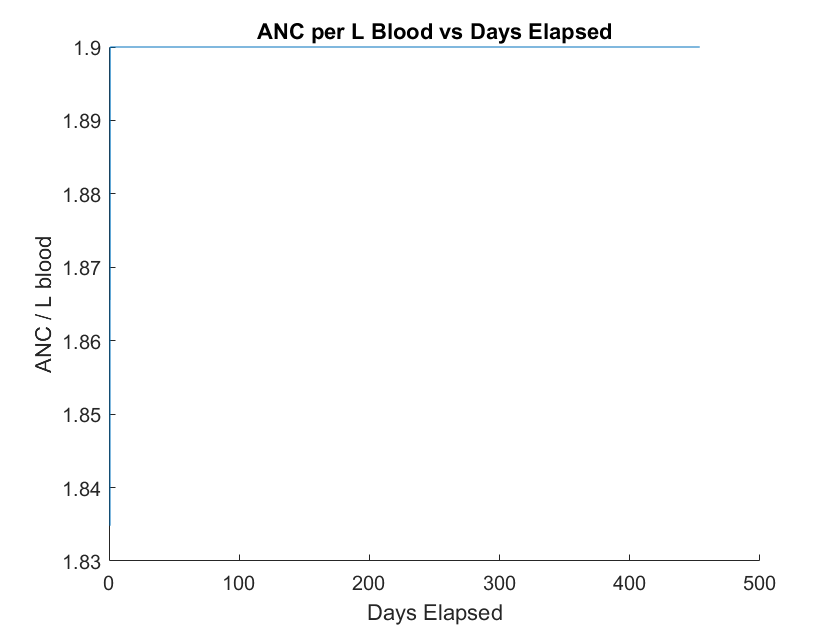

% Simulation length based on time vector
t_s = step_size;
start_time = patient_cycles(1,1);
end_time = patient_cycles(end,2);
N_days = round(abs(start_time-end_time));
N_steps = round(N_days / t_s);
N_steps_per_day = 1 / t_s;
time = (start_time:t_s:end_time);

u_nominal = zeros([N_steps 1]);
rho = ones([N_steps 1]) * 1.9; % nominal trajectory is just a setpoint

u_k=50*bsa;
rho(1,:) = g_nonlin(x0);
cycle_index = 1;

for k=1:N_days
    cycle_length = patient_cycles(cycle_index, 3);
    day_in_cycle = get_cycle_day(k, cycle_length);
    for i=1:N_steps_per_day
        j = (N_steps_per_day*(k-1) + i);
        % for comparison with Jost data, drug is administered everyday
        u_nominal(j,:) = u_k;
    end
    if day_in_cycle == cycle_length
        x_k8 = rho(j+1,:);
        if x_k8 < lower
            u_k = 0.8*u_k;
        elseif x_k8 > upper
            u_k = 1.2*u_k;
        end
    end
end

figure()
hold on
xlabel('Days Elapsed')
ylabel('ANC / L blood')
title("ANC per L Blood vs Days Elapsed")
plot(time,rho)
hold off

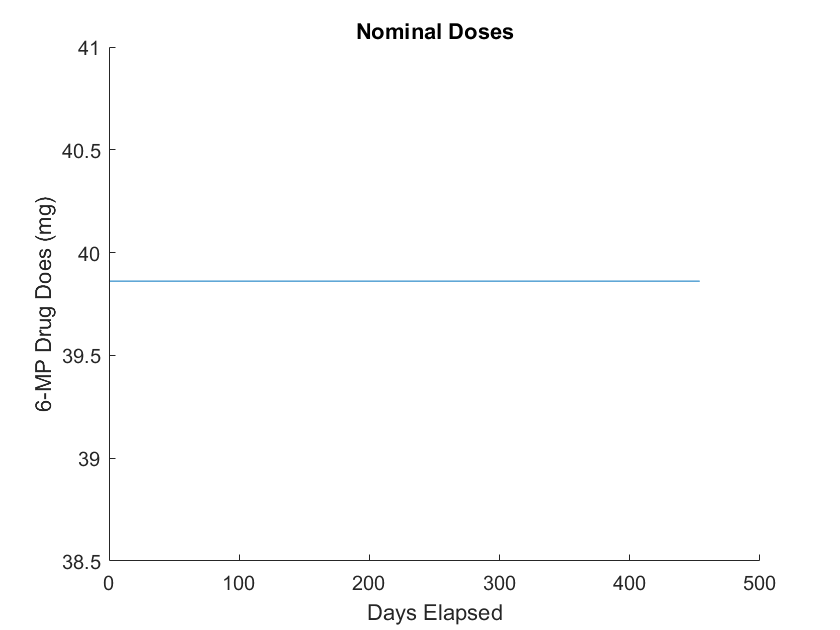


figure()
hold on
xlabel('Days Elapsed')
ylabel('6-MP Drug Does (mg)')
title("Nominal Doses")
plot(time,u_nominal)
hold off

## Adaptive Model Predictive Controller

N_cyclespred = 5;

n_params = length(p_actual);
x_calc = []; %zeros([n,1,N_steps+1]);
y_calc = []; %zeros([m,1,N_steps+1]);
params_calc = []; %zeros([n_params,1,length(patient_cycles)+1]);
u_calc = zeros([1,N_days]);

x_calc(:,:,1) = x0;
y_calc(:,:,1) = g_nonlin(x0);
params_calc(:,:,1) = p_guess;
cycle = 1;

k = 0;
while k < N_days && cycle <= size(patient_cycles,1)
    prev_step = size(x_calc,3);  
    N_cycledays = patient_cycles(cycle,3);
    N_drugdays = N_cycledays;
    
    f = @(p)calc_params(p, p_actual, x0, u_calc, prev_step, N_cycledays, N_cycledays, t_s);
    [p_star, fval] = fmincon(f,params_calc(:,:,cycle));
    
    g = @(u)calc_control_comparison(...
        p_star, rho, x_calc(:,:,prev_step), k, cycle, u, 10, 0.0001, ...
        N_cyclespred, N_cyclespred, patient_cycles, t_s ...
    );
    
    init_guess_u = 50*bsa;
    [u_star, gval] = fmincon(g,repmat(init_guess_u, [N_cyclespred 1]), [], [], [], [], repmat(0.01, [N_cyclespred 1]));
    u_calc(k+1:k+N_drugdays) = u_star(1);
    
    params_calc(:,:,cycle+1) = p_star;
    
    for i=prev_step:prev_step + N_steps_per_day*N_cycledays - 1
        x_calc(:,:,i+1) = jost_discrete((i+1)*t_s,x_calc(:,:,i), u_calc(k+1),p_actual,N_cycledays,N_drugdays,t_s);
        y_calc(:,:,i+1) = g_nonlin(x_calc(:,:,i+1));
    end
    
    cycle = cycle + 1;
    k = k + N_cycledays;    
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## Plots

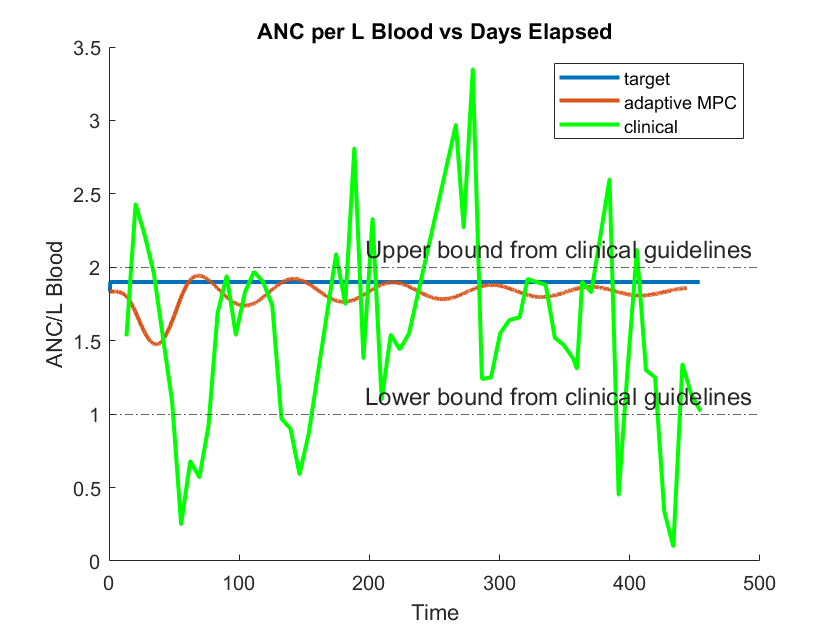

u_calc_full = zeros(size(u_nominal));
for k=1:N_days
    i = N_steps_per_day*(k-1);
    u_calc_full(i+1:i+N_steps_per_day,:) = u_calc(k)*(ones(N_steps_per_day,1));
end

y_neutrophils = reshape(y_calc(1,1,:),[1 size(y_calc, 3)]);
figure()
hold on
plot(time,rho, "LineWidth", 2)
plot(time(1:length(y_neutrophils)), y_neutrophils, "LineWidth", 2)
plot(patient_data(:,1), patient_data(:,2), "LineWidth", 2, "Color", "green")
title('ANC per L Blood vs Days Elapsed')
ub = yline(2, "-.", "Upper bound from clinical guidelines");
lb = yline(1, "-.", "Lower bound from clinical guidelines");
ub.FontSize = 12;
lb.FontSize = 12;
xlabel('Time')
ylabel('ANC/L Blood')
legend('target','adaptive MPC', "clinical")
hold off

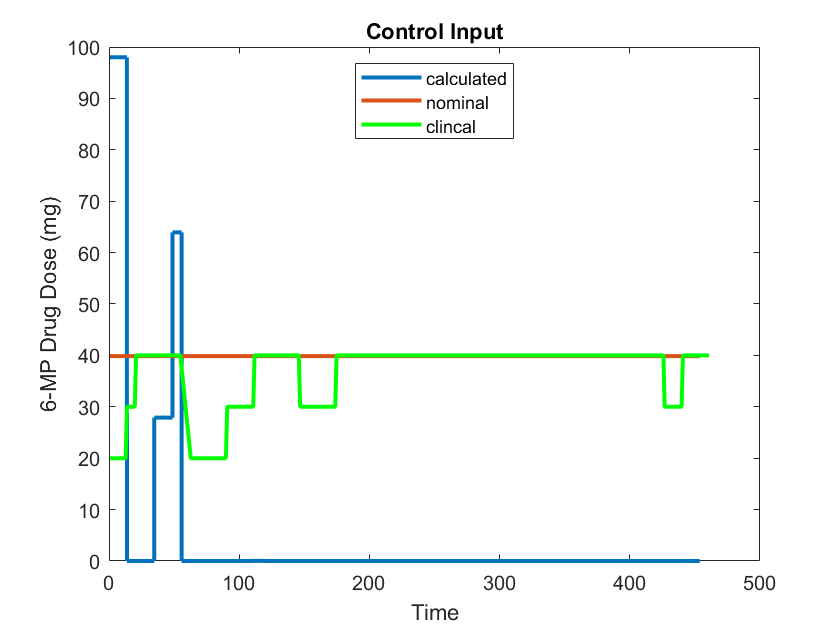


figure()
plot(time,u_calc_full, "LineWidth", 2)
hold on
plot(time,u_nominal, "LineWidth", 2)
plot(patient_doses(:,1), patient_doses(:,2), "Color", "green", "LineWidth", 2)
title('Control Input')
xlabel('Time')
ylabel('6-MP Drug Dose (mg)')
l = legend('calculated','nominal', 'clincal');
l.Location = "north";
hold off

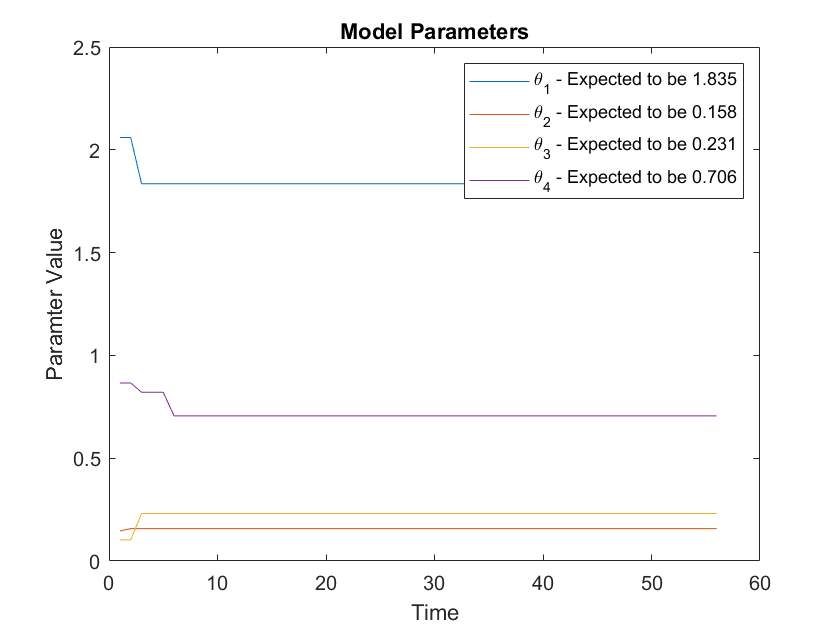


p1 = reshape(params_calc(1,1,:),[1 cycle]);
p2 = reshape(params_calc(2,1,:),[1 cycle]);
p3 = reshape(params_calc(3,1,:),[1 cycle]);
p4 = reshape(params_calc(4,1,:),[1 cycle]);
figure()
plot(p1)
hold on
plot(p2)
hold on
plot(p3)
hold on
plot(p4)
title('Model Parameters')
xlabel('Time')
ylabel('Paramter Value')
legend(...
    sprintf('%s - Expected to be %0.3f', "\theta_1", p_actual(1)), ...
    sprintf('%s - Expected to be %0.3f', "\theta_2",p_actual(2)), ...
    sprintf('%s - Expected to be %0.3f', "\theta_3",p_actual(3)), ...
    sprintf('%s - Expected to be %0.3f', "\theta_4",p_actual(4)) ...
)
hold off